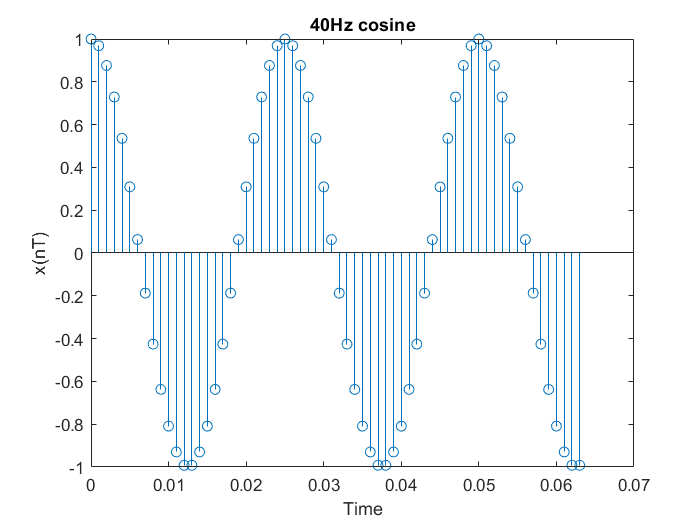

clear all;
close all;
clc;

% To some extent, here the content in variable x and sample_data are the
% same, this was due to the reason that when x was created, the n*T was
% exactly the same as used in sampling. n*T will decide how long the signal
% is in time domain.

% Remember everything that a computer can process and handle should be in
% discrete form, this is why when generate signal, time variable is not
% continuous, and we are to some extent 'lying to' the computer (or to
% ourselves) that the signal is continuous or analogue :)

% Generates a 40Hz cosine wave
%
N = 64; % 64 data points
fs = 1000; % 1kHz sampling frequency
T = 1/fs; % sample period
i = 40; % signal frequency in Hz
n = 0:N-1; % discrete time vector
x = cos(2*pi*i*n*T); %signal definition
%plot the signal against time
y = stem(n*T,x);
sample_data = y.YData;
title('40Hz cosine')
xlabel('Time')
ylabel('x(nT)')

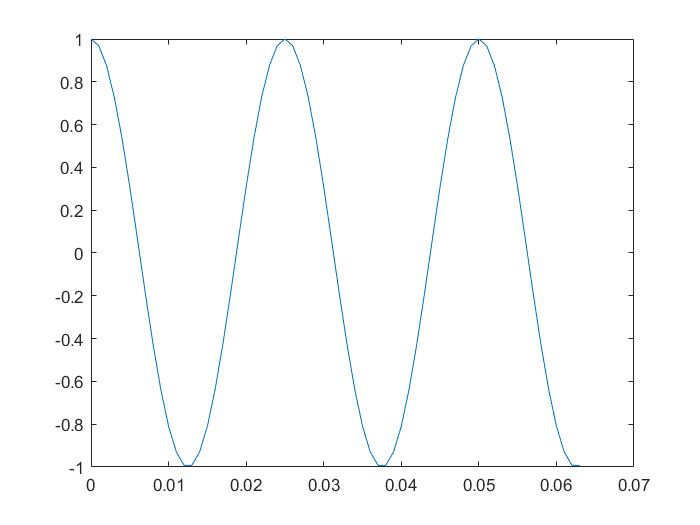


plot(n*T,x);

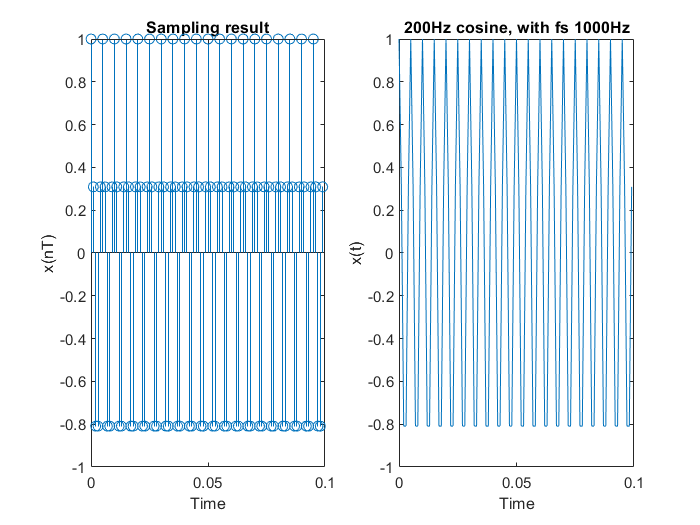

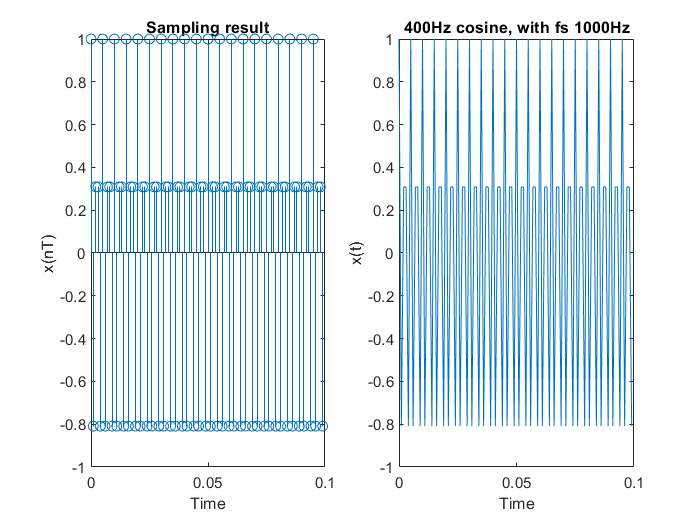

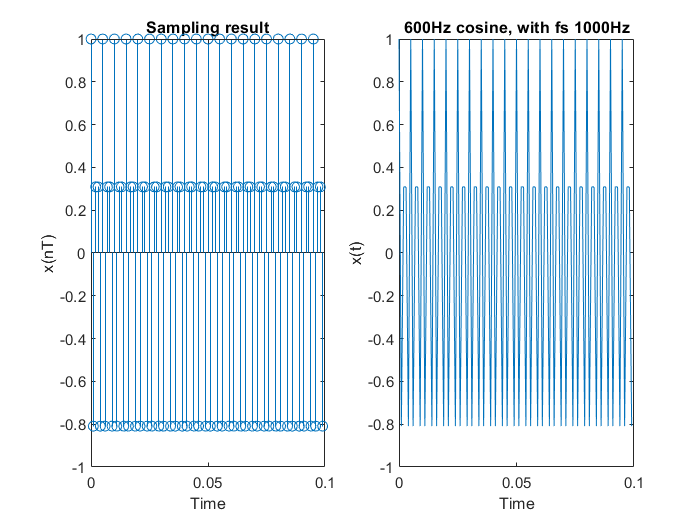

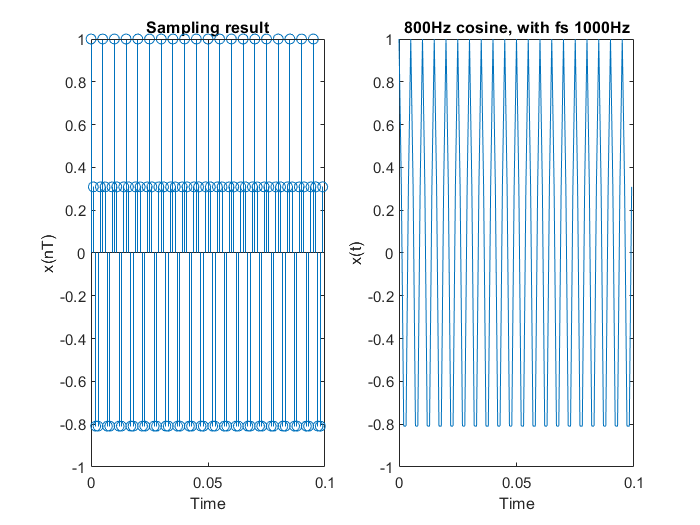

clear all;
close all;
clc;
fs = 1000;
T = 1/fs;
N = 100;
n = 0:N-1;
for i = 1:4
    figure;
    x = cos(2*pi*i*200*n*T); %signal definition
    %plot the signal against timeabel('x(nT)');
    subplot(1,2,1);
    stem(n*T,x)
    title('Sampling result');
    xlabel('Time')
    ylabel('x(nT)')
    hold on;
    subplot(1,2,2);
    plot(n*T,x);
    title([num2str(i*200) 'Hz cosine, with fs 1000Hz']);
    xlabel('Time');
    ylabel('x(t)')
    hold off;
end

clear all;
close all;
clc;
fs = 10000;
T = 1/fs;
N = 1000;
n = 0:N-1;
for i = 200:200:800
    figure;
    x = cos(2*pi*i*n*T); %signal definition
    %plot the signal against time
    stem(n*T,x)
    hold on;
    plot(n*T,x);
    title([num2str(i) 'Hz cosine, with fs 10000Hz']);
    xlabel('Time');
    ylabel('x(nT)');
    hold off;
end
soundsc(interp(x,8),8*fs)


And then we consider the reconstruction of the signal.

And I noticed that if the sampling frequency for the sinc function is the same as that of the sampling frequency for original singal, we may even not be able to plot a 'right' continuous sinc function, see as below:

% Assume Ts = 1e-4 for original signal.
clear all;
close all;
clc;

x =  -10 * 1e-4:1e-4:10 * 1e-4;
y = sinc(x / 1e-4);
plot(x,y);
hold on;
x =  -10 * 1e-4:1e-5:10 * 1e-4;
y = sinc(x / 1e-4);
plot(x,y);
legend('10kHz Samping frequency','100kHz Sampling frequency');
xlabel('Time');
ylabel('Amplitude of sinc(t)');

% Case where sampling rate for original signal and sinc are the same.
% In this case we may even not be able to plot a 'right' sinc function.

clear all;
close all;
clc;

M = zeros(1021, 1000);
sinc_result= zeros(1021, 1000);
for i = 1:1000
    x = (-10 + i - 1) * 1e-4:1e-4:(10 + i - 1) * 1e-4;
    M([i:i+20], i) = x;
    sinc_result([i:i+20], i) = sinc((M([i:i+20], i)- (i-1) * 1e-4) / 1e-4);
    %     plot(M([i:i+20], i), sinc_result([i:i+20], i));
    %     hold on;
    %     grid on;
end
% hold off;

N = 1000; % 1000 data points
fs = 10000; % 10kHz sampling frequency
T = 1/fs; % sample period
f = 200; % signal frequency in Hz
n = 0:N-1; % discrete time vector
x = cos(2*pi*f*n*T); %signal definition
%plot the signal against time
y = stem(n*T,x);
sample_data = y.YData
title('200Hz cosine')
xlabel('Time')
ylabel('x(nT)')

plot(n*T,x);

signal_recover_times_samples = sample_data .* sinc_result;
signal_recover_final = sum(signal_recover_times_samples, 2);
x = -10 * T:1e-4:0.1 + 10 * T
plot(x, signal_recover_final)

In the above case, we can see that even though the sinc function could not be plotted in a right way, but the reconstruction result was still really good, and we can see that at the beginning and end of the recovered signal, there was 0, this was due to the reason that, we truncated the sinc function witnin +-10T range, and since the sampling frequency for the sinc signal was not high enough, at the beginning and end of the sinc signal, the function value was 0.

% If we increase the sampling frequency for sinc?
% Here sampling sinc at 100kHz (The cheating frequency for sinc)
clear all;
close all;
clc;

M = zeros(10201, 1000);
sinc_result= zeros(10201, 1000);
for i = 1:1000
    %     Use 100kHz to 'cheat' in the sinc function.
    x = (-10 + i - 1) * 1e-4:1e-5:(10 + i - 1) * 1e-4;
    M(1+(i-1)*10:1+(i-1)*10+200, i) = x;
    sinc_result([1+(i-1)*10:1+(i-1)*10+200], i) = sinc( (M(1+(i-1)*10:1+(i-1)*10+200, i)- (i-1) * 1e-4) / 1e-4);
end

N = 1000; 
fs = 10000; % 10kHz sampling frequency
T = 1/fs; % sample period
T_for_cheating = 1/10 * T; % Cheating frequency for cos is 100kHz.
f = 200; % signal frequency in Hz
n = 0:N-1; % discrete time vector
% Since we change the cheating frequency for the cos, we also have to
% change the number of samples to make sure that we plot the cos for 0.1
% second.
n_for_cheat = 0:10000;
x = cos(2*pi*f*n*T);
x_for_cheat = cos(2*pi*f*n_for_cheat*T_for_cheating); %signal definition, 'cheat' here by 10 times the sampling frequency.
%plot the signal against time
subplot(4,1,1);
y = stem(n*T,x);
title('Sampled data');
sample_data = y.YData;
title('200Hz cosine in samples');
xlabel('Time');
ylabel('x(nT)');

subplot(4,1,2);
plot(n_for_cheat,x_for_cheat);
title('200Hz cosine');
xlabel('Time');
ylabel('x(t)');

signal_recover_times_samples = sample_data .* sinc_result;
signal_recover_final = sum(signal_recover_times_samples, 2);
x = -10 * T:1e-5:0.1 + 10 * T;
subplot(4,1,3);
plot(x, signal_recover_final);
title('Recovered 200Hz cosine by sinc function');
xlabel('Time');
ylabel('x(t)');

% At the beginning and end of the recovering curve, the recovering result
% was not satisfactory, I think this was due to the reason that both at the
% beginning and end of the curve, there was not enough sinc function value
% to help build the recover signal (because we tuncated the sinc function
% within +-10T and think about the mathematic representation of the
% recovered signal, which is the summation of the sinc times corresponding
% sample data value, there was not enough sinc function value at the
% beginning of the recovered signal (actually only one sinc function value
% at the first few recovered signal points), the recovered signal value was
% exactly the value of sinc function at the beginning and end.)

subplot(4,1,4);
fmagplot(sample_data, 1e-4);

ans = 5

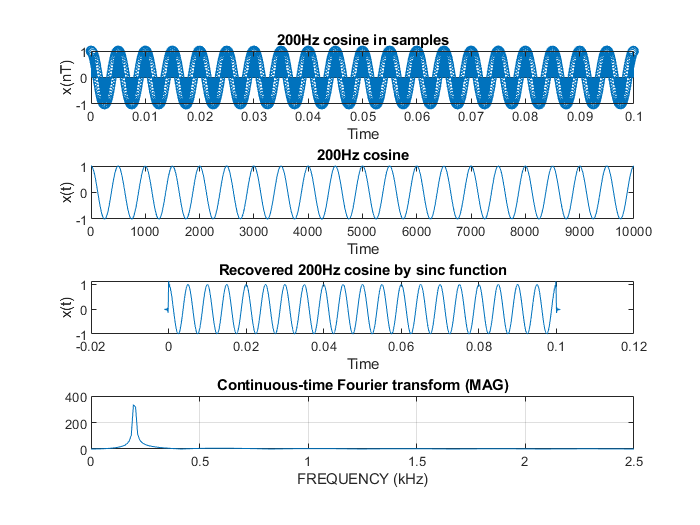


hold off;

figure

subplot(4,2,1);
fmagplot(x_for_cheat,1e-5);

ans = 5

subplot(4,1,2);
fmagplot(sample_data, 1e-4);

ans = 5

subplot(4,1,3);
fmagplot(sinc_result(1:21,1), 1e-5);

ans = 5

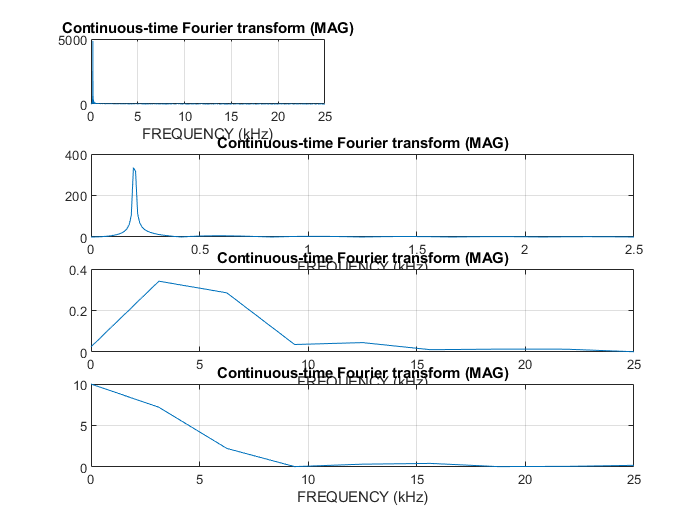

ans = 5

subplot(4,1,4);
x = -1e-4:1e-5:1e-4;
linear_result = (1e-4 - abs(x)) / 1e-4;
fmagplot(linear_result, 1e-5);

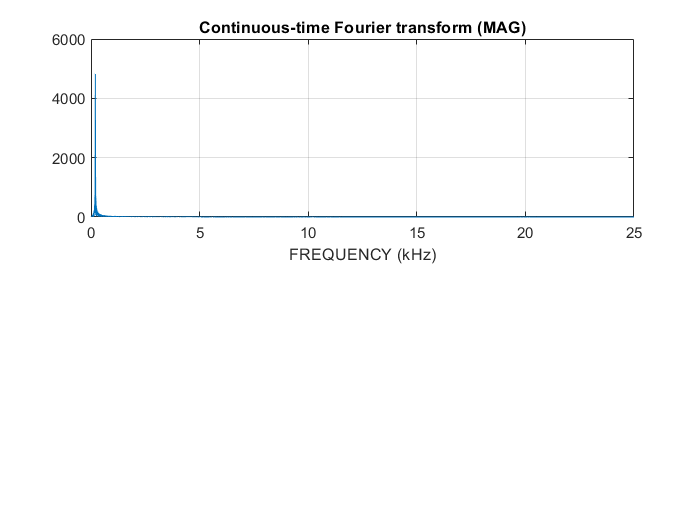

ans = 5


figure
% Frequency plot for recovered signal based on sinc.
subplot(2,1,1);
fmagplot(signal_recover_final, 1e-5);

Now we go back to the case where we do not use the sinc function, which corresponds to the ideal low pass filter, we use the linear interpolation function which has the expression of h(t) = (T - abs(t)) / T

% Assume again the sampling frequency for the linear interpolation function
% is 100kHz again, with period 1e-5s.
clear all;
close all;
clc;

M = zeros(10021, 1000);
linear_result= zeros(10021, 1000);
for i = 1:1000
    x = -1e-4:1e-5:1e-4; % Range of -T to T.
    %     Put the value directly into different places of the matric, since
    %     even though we shift the function, we shift the range of x at the
    %     same time, this equals to the same value of function but at different
    %     places.
    M(1+(i-1)*10:1+(i-1)*10+20, i) = x;
    linear_result([1+(i-1)*10:1+(i-1)*10+20], i) = (1e-4 - abs(M(1+(i-1)*10:1+(i-1)*10+20, i))) / 1e-4;
end

N = 1000; % 1000 data points
fs = 10000; % 10kHz sampling frequency
T = 1/fs; % sample period
f = 200; % signal frequency in Hz
n = 0:N-1; % discrete time vector
n_for_cheat = 0:10000;
x = cos(2*pi*f*n*T); 
x_for_cheat = cos(2*pi*f*n_for_cheat*T*1/10); %signal definition, 'cheat' here by 10 times the sampling frequency.
%plot the signal against time
subplot(4,1,1);
y = stem(n*T,x);
title('Sampled data');
sample_data = y.YData;
title('200Hz cosine in samples');
xlabel('Time');
ylabel('x(nT)');

subplot(4,1,2);
plot(n_for_cheat,x_for_cheat);
title('200Hz cosine');
xlabel('Time');
ylabel('x(t)');


signal_recover_times_samples = sample_data .* linear_result;
signal_recover_final = sum(signal_recover_times_samples, 2);
x = -1e-4:1e-5:0.1 + 1e-4

x =    -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100         0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900


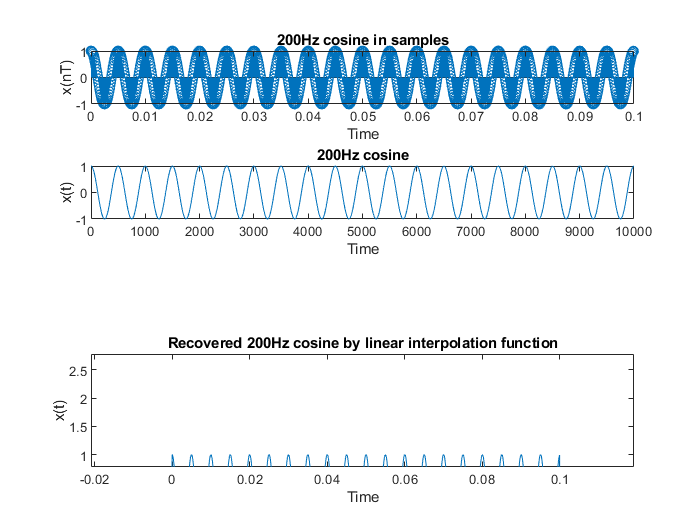

subplot(3,1,3);
plot(x, signal_recover_final);
title('Recovered 200Hz cosine by linear interpolation function');
xlabel('Time');
ylabel('x(t)');

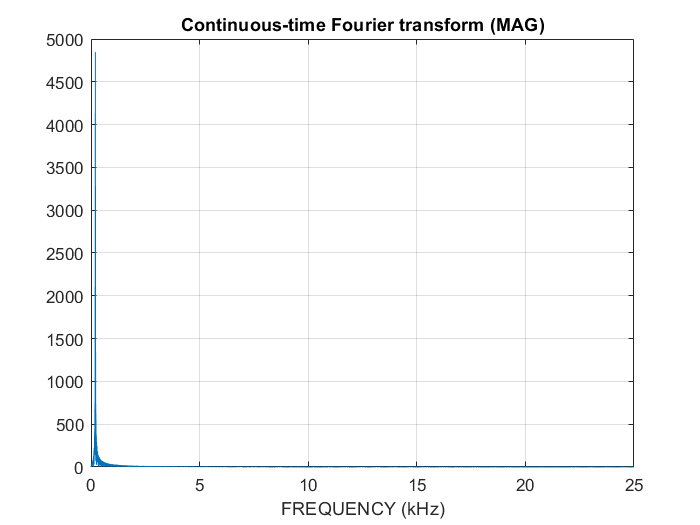

ans = 5


figure
fmagplot(signal_recover_final, 1e-5)